clc;
close all;
clear all;

Rango = 1000;
[RPM,z] = datos_RPM();
tiempo = linspace(0,Rango,z);

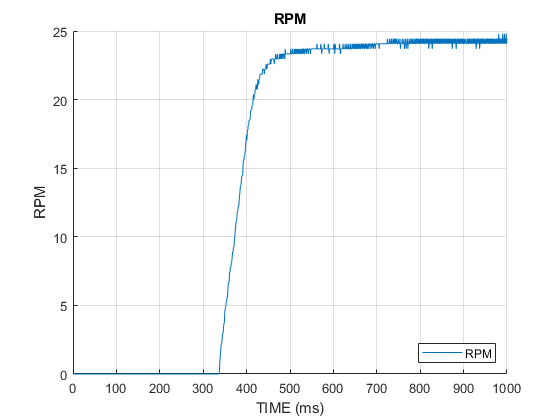

hold on

plot(tiempo,RPM)
title('RPM')
legend('RPM','Location','southeast')
ylabel('RPM')
xlabel('TIME (ms)')
grid on

ultimos_100_datos = RPM(end-99:end); % Tomar los últimos 100 datos
promedio_ultimos_100 = mean(ultimos_100_datos); % Calcular el promedio de los últimos 100 datos
vf= promedio_ultimos_100

vf = 24.2587

vf283 = vf*0.283

vf283 = 6.8652

vf632 = vf*0.632

vf632 = 15.3315

Vt1=vf*0.283

Vt1 = 6.8652

% 
for tiempo = 1:z
    RPM_actual=RPM(tiempo);
    if RPM_actual <= Vt1
        t1_min=tiempo;
        RPM_min=RPM_actual;
    end
    if RPM_actual >= Vt1
        t1_max=tiempo;
        RPM_max=RPM_actual;
        break;
    end
end
t1_min

t1_min = 360

RPM_min

RPM_min = 6.6700


t1_max

t1_max = 361

RPM_max

RPM_max = 7.4100

y1=t1_min;
y2=t1_max;
x1=RPM_min;
x2=RPM_max;
x=Vt1;
t1=y1 + ((y2-y1)/(x2-x1))*(x-x1)

t1 = 360.2638


Vt2=vf*0.632

Vt2 = 15.3315

for tiempo = 1:z
    RPM_actual=RPM(tiempo);
    if RPM_actual <= Vt2
        t1_min=tiempo;
        RPM_min=RPM_actual;
    end
    if RPM_actual >= Vt2
        t1_max=tiempo;
        RPM_max=RPM_actual;
        break;
    end
end
y1=t1_min;
y2=t1_max;
x1=RPM_min;
x2=RPM_max;
x=Vt2;
t2=y1 + ((y2-y1)/(x2-x1))*(x-x1)

t2 = 392.3824

%hallar Tetha
% 
% for tetha = 1:z
%     if RPM(tetha)>0
%         break;
%     end
% end
% tetha
% %hallar Taou 
% 
% Tao=t2-tetha
% 
% Tao=(t1-tetha)*3
% Primer orden



deltaY = vf

deltaY = 24.2587

deltaU = 1

deltaU = 1

% Definimos las variables simbólicas x e y
syms tetha Tao

% Definimos las dos ecuaciones que queremos resolver
eqn1 = tetha + Tao/3 == t1;
eqn2 = tetha + Tao == t2;

% Resolvemos el sistema de ecuaciones para las variables x e y
sol = solve([eqn1, eqn2], [tetha, Tao]);

% Obtenemos el valor numérico de cada variable
tetha = double(sol.tetha)

tetha = 344.2045

Tao = double(sol.Tao)

Tao = 48.1779


k=deltaY/deltaU

k = 24.2587


syms s
Gs = (k*exp(-tetha*s))/(Tao*s+1)

$$Gs = \frac{1707054254382699\,{\mathrm{e}}^{-\frac{1513827339412409\,s}{4398046511104}}}{70368744177664\,\left(\frac{1695110636375775\,s}{35184372088832}+1\right)}$$

% Compute simplified symbolic expression
simplifiedExpr = simplify(Gs)

$$simplifiedExpr = \frac{1707054254382699\,{\mathrm{e}}^{-\frac{1513827339412409\,s}{4398046511104}}}{2\,\left(1695110636375775\,s+35184372088832\right)}$$

var = vpa(Gs)

$$var = \frac{24.258700000000018803802959155291\,{\mathrm{e}}^{-344.20448614864858427608851343393\,s}}{48.177941959459502641038852743804\,s+1.0}$$

s=tf('s'); 
Gsfinal=((exp(-344.2044*s))*24.2587)/(48.1779*s + 1);
Gsfinal


Gsfinal =
 
                   24.26
  exp(-344*s) * -----------
                48.18 s + 1
 
Continuous-time transfer function.



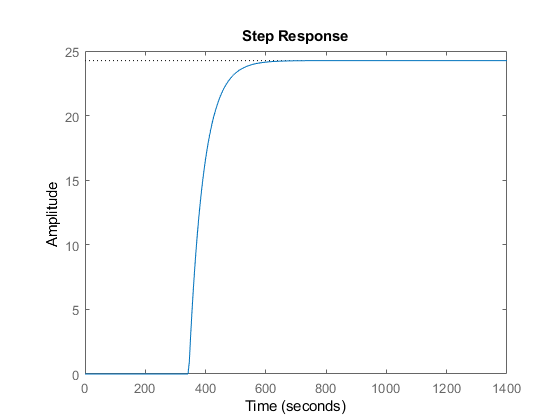

step(Gsfinal)

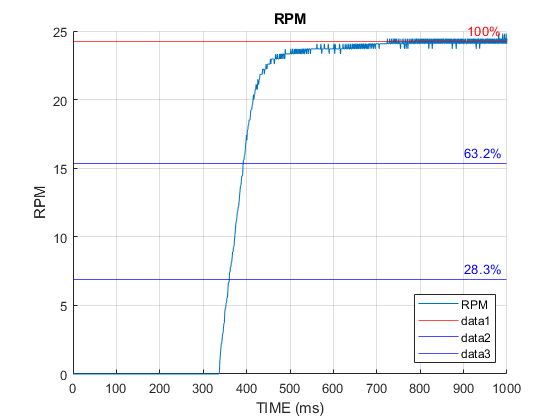

yline(vf, 'r', '100%');
yline(vf*0.283, 'B', '28.3%');
yline(vf*0.632, 'B', '63.2%');

%segundo orden

t1s=150

t1s = 150

t2s=450

t2s = 450

t3s=750

t3s = 750

Ts =0.001

Ts = 1.0000e-03

tmin=4*Tao

tmin = 192.7118

tmax=5*Tao

tmax = 240.8897

x = (t2s - t1s)/(t3s - t1s)

x = 0.5000

chi = (0.0805 - 5.547*(0.475 - x)^2)/(x - 0.356)

chi = 0.5350

F2chi = (0.708*(2.811)^chi)

F2chi = 1.2307

Wn = F2chi/(t3s - t1s)

Wn = 0.0021

F3chi = 0.922 * (1.66)^chi

F3chi = 1.2091

thetap = (t2s) - (F3chi/Wn)

thetap = -139.4909


tao1 = (chi - sqrt(chi^2-1))/Wn

tao1 = 2.6080e+02 - 4.1190e+02i

tao2 = (chi + sqrt(chi^2-1))/Wn

tao2 = 2.6080e+02 + 4.1190e+02i

syms s e
Gp = (k*(Wn)^2*(e^-thetap*s))/(s^2 +(2*chi*Wn*s)+(Wn^2))

$$Gp = \frac{3765472683141471\,e^{613487493219851/4398046511104}\,s}{36893488147419103232\,\left(s^{2}+\frac{5060295575303597\,s}{2305843009213693952}+\frac{4967089162260425}{1180591620717411303424}\right)}$$

var = vpa(Gp)

$$var = \frac{0.00010206334158742010813185341344678\,e^{613487493219851/4398046511104}\,s}{s^{2}+0.002194553382465178146404349845966\,s+0.0000042072881723843414273678910364485}$$

%s=tf('s'); 
%Gpfinal=(0.00010097491613722420103309296290917*e^(613487493219851/4398046511104)*s)/(s^2 + 0.002194553382465178146404349845966*s + 0.0000042072881723843414273678910364485);



%Creamos lineas indicadoras para los porcentajes de interes
yline(vf, 'r', '100%');
yline(vf*0.75, 'g', '75%');
yline(vf*0.45, 'b', '45%');
yline(vf*0.15, 'm', '15%');
yline(0, 'k', '0%');

legend("Position", [0.22196,0.42278,0.16778,0.2443])
num=[0.00010097491613722420103309296290917*exp(613487493219851/4398046511104) 0];
den=[1  0.002194553382465178146404349845966 0.0000042072881723843414273678910364485];
Gpfinal = tf(num,den)


Gpfinal =
 
           3.84e56 s
  ----------------------------
  s^2 + 0.002195 s + 4.207e-06
 
Continuous-time transfer function.



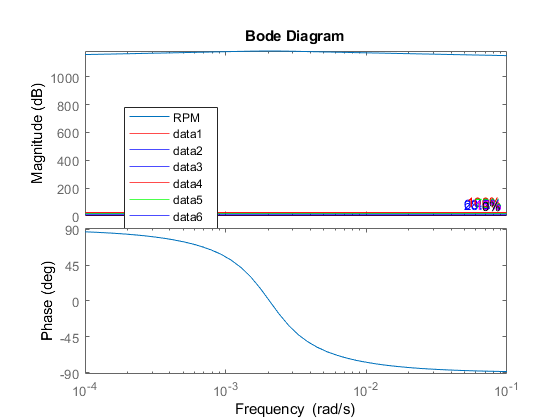

bode(Gpfinal);

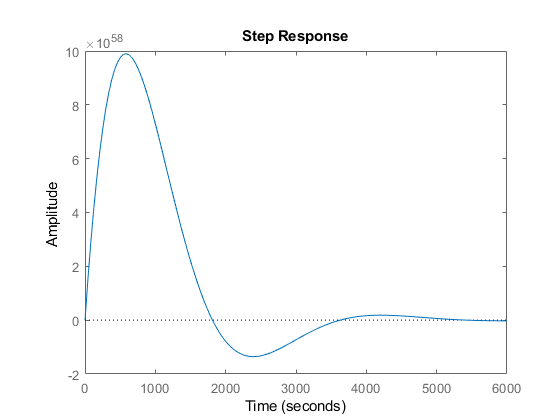

figure;
step(Gpfinal);